# Single-column model -- preliminary work

This is a MATLAB code that implements a single-column model, which is a type of atmospheric model that is commonly used to study the vertical structure of the atmospheric boundary layer (ABL). The ABL is the layer of the atmosphere that is in contact with the Earth's surface, and it is characterized by turbulent mixing that is driven by buoyancy forces and wind shear.

The code is divided into two main parts, depending on whether temperature data is available or not. In the first case, where no temperature data is available, an explicit formulation for the eddy viscosity coefficient (Km) is provided, and the model equations are solved for four different parameterizations of Km. In the second case, where temperature data is available, no explicit formulation for Km is provided, and the model equations are solved once with a Monin-Obukhov (MO) theory-based formulation for Km.

The code first sets up the parameters for the model, such as the depth of the ABL, the number of grid points along the vertical direction, the latitude of the location being studied, and the roughness length of the surface. It then defines the functions that are used to calculate the eddy viscosity coefficient, K, for the different parameterizations that are being tested.

Finally, the code solves the model equations for each parameterization, using the boundary and initial conditions that are specified, and plots the resulting velocity profiles as a function of height. The outputs of the model, such as the velocity, temperature, and eddy viscosity coefficient, are then processed and stored for later analysis.

## Case where no-temperature data available  + explicit formulation for Km

clearvars;close all;
h = 1000; % ABL depth
zmax = 0.99*h;
Nz = 200; % numbers of grid point along z direction
latitude = 53;
z0 = 0.001; % roughness length
z = logspace(log10(z0),log10(zmax),Nz);


### Define the eddy viscosity functions

With explicit formulation for Km Definitions of K1,K2, K3 and K4 following [1]. I used anonymous functions to define K2,K3 and K4

[1] Berger, B. W., & Grisogono, B. (1998).  The baroclinic, variable eddy viscosity Ekman layer. Boundary-layer meteorology, 87(3), 363-380.

getK_V1 = @(K0,K_hat,K_star,z_star,z)  K_hat + (K0-K_hat).*exp(z/z_star.*(log((K_star-K_hat)./(K0-K_hat))));
getK_V2 = @(a0,a1,K0,K_hat,K_star,z_star,z)  (a0 + a1.*z).*K0.*exp(z/z_star.*(log((K_star-K_hat)./(K0-K_hat))));


% derivative of K w.r.t. z
get_K1_p = @(K0,K_hat,K_star,z_star,z) (exp((z.*log(-(K_hat - K_star)./...
    (K0 - K_hat)))./z_star).*log(-(K_hat - K_star)./(K0 - K_hat))*(K0 - K_hat))./z_star;
getK_V2_p = @(a0,a1,K0,K_hat,K_star,z_star,z)  K0*a1*exp((z*log(-(K_hat - K_star)./...
    (K0 - K_hat)))./z_star) + (K0.*exp((z.*log(-(K_hat - K_star)./(K0 - K_hat)))./z_star).*...
    log(-(K_hat - K_star)./(K0 - K_hat)).*(a0 + a1*z))./z_star;
 


Nk = 4;
K = zeros(Nk,Nz);
Kp = zeros(Nk,Nz); % derivative of K w.r.t. z

% Case 1
K(1,:) = 1.3.*ones(1,Nz); % K1

% Case 2
K0 = 0.7; K_hat = 5.5; K_star = 4.5; z_star = 500;
K(2,:) = getK_V1(K0,K_hat,K_star,z_star,z); % K2
Kp(2,:) = get_K1_p(K0,K_hat,K_star,z_star,z);


% Case 3
K0 = 1.4; K_hat = 0.7; K_star = 0.8; z_star = 500;
K(3,:) = getK_V1(K0,K_hat,K_star,z_star,z); % K3
Kp(3,:) = get_K1_p(K0,K_hat,K_star,z_star,z);

% Case 4
a0 = 0.9; a1 = 2.7/50; K0 = 0.45; K_hat = 0.1; K_star = 0.3; z_star = 250;
K(4,:) = getK_V2(a0,a1,K0,K_hat,K_star,z_star,z); % K4
Kp(4,:) = getK_V2_p(a0,a1,K0,K_hat,K_star,z_star,z); % K4


### Solve the single-column model equations

figure
for ii=1:Nk
    opts = bvpset('RelTol',0.01,'AbsTol',0.01,'Stats','on');
    clear para
    para.Km = K(ii,:) ; % No explicit formulation for Km --> MO theory is used
    para.Kh = para.Km ; % No explicit formulation for Km --> MO theory is used
    para.L = inf; % Obukhov length
    para.u_star = 0.25; % initial conditions
    para.h = h;
    para.alpha = 1;
    para.model = [];
    para.bc_theta = []; % boundary and initial conditions: [top-bottom]
    para.bc_u = [10 0];% boundary and initial conditions: [top-bottom]
    para.bc_v = [0 0]; % boundary and initial conditions: [top-bottom]
    
    [sol4c] = scm_bcp4v(latitude,para,z,opts,'Km_p',Kp(ii,:));
    
    myZ = sol4c.x;
    myU = sol4c.y(1,:);

    plot(myU,myZ)
    hold on; box on;
    xlabel('u (m s^{-1})')
    ylabel('height (m)')
    set(gcf,'color','w')
end

The solution was obtained on a mesh of 200 points.
The maximum residual is  3.993e-06. 
There were 1997 calls to the ODE function. 
There were 16 calls to the BC function. 


The solution was obtained on a mesh of 200 points.
The maximum residual is  1.022e-06. 
There were 2396 calls to the ODE function. 
There were 17 calls to the BC function. 


The solution was obtained on a mesh of 200 points.
The maximum residual is  6.507e-06. 
There were 1997 calls to the ODE function. 
There were 16 calls to the BC function. 


The solution was obtained on a mesh of 200 points.
The maximum residual is  3.543e-06. 
There were 2396 calls to the ODE function. 
There were 17 calls to the BC function. 


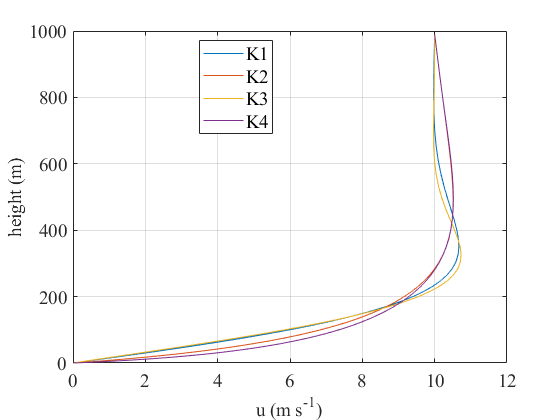

grid on
legend('K1','K2','K3','K4','location','best')
set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')

## No explicit formulation for Km + with temperature data

opts = bvpset('RelTol',0.01,'AbsTol',0.01,'Stats','on');
clear para
para.Km = [] ; % No explicit formulation for Km --> MO theory is used
para.Kh = para.Km ; % No explicit formulation for Km --> MO theory is used
para.model = [];
para.L = -1000; % Obukhov length
para.u_star = 0.25; % initial conditions
para.h = h;
para.alpha = 1;
para.bc_theta = [273 285]; % boundary and initial conditions: [top-bottom]
para.bc_u = [10 0];% boundary and initial conditions: [top-bottom]
para.bc_v = [0 0]; % boundary and initial conditions: [top-bottom]


###  Solve the single-column model equations

[sol4c,Km,Kh] = scm_bcp4v(latitude,para,z,opts);

The solution was obtained on a mesh of 100 points.
The maximum residual is  9.917e-04. 
There were 23001 calls to the ODE function. 
There were 240 calls to the BC function. 



% Process the outputs
if ~isempty(para.bc_theta),
    u = sol4c.y(1,:);
    v = sol4c.y(2,:);
    theta = sol4c.y(3,:);
    dudz = sol4c.y(4,:);
    dvdz = sol4c.y(5,:);
    dTdz = sol4c.y(6,:);
    wT = -Kh.*dTdz;
else
    u = sol4c.y(1,:);
    v = sol4c.y(2,:);
    dudz = sol4c.y(3,:);
    dvdz = sol4c.y(4,:);
end

uw = -Km.*dudz;
vw = -Km.*dvdz;
u_star = ((uw).^2 + (vw).^2).^0.25 ;

### Results

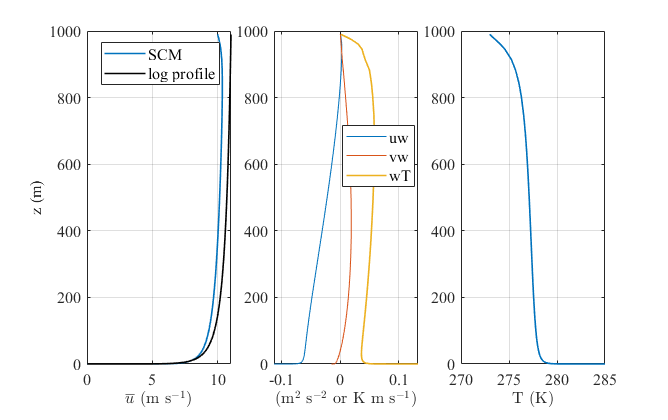

clf;close all
figure('position',[521   379   668   420]);
if ~isempty(para.bc_theta),
    tiledlayout(1,3,'TileSpacing','compact')
else
    tiledlayout(1,2,'TileSpacing','compact')
end

nexttile
meanU = sqrt(u.^2 +v.^2);
plot(meanU ,sol4c.x,'linewidth',1.2)
[~,indZ]=min(abs(sol4c.x-10));
hold on
uref_sim =  meanU(indZ);
u1 = velProfile(para.u_star,sol4c.x,z0,para.L);
uref_log =  u1(indZ);
plot(u1.*uref_sim./uref_log,sol4c.x,'k','linewidth',1.2);
ylabel('z (m)')
xlabel('$\overline{u}$ (m s$^{-1}$)','interpreter','latex')
grid on
legend('SCM','log profile')

nexttile
plot(uw,sol4c.x)
hold on
plot(vw,sol4c.x)
if ~isempty(para.bc_theta),
    plot(wT,sol4c.x,'linewidth',1.2)
    legend('uw','vw','wT','location','best')
else
    legend('uw','vw','location','best')
end
xlabel('(m$^2$ s$^{-2}$ or K m s$^{-1}$)','interpreter','latex')
grid on

if ~isempty(para.bc_theta),
    nexttile
    plot(theta,sol4c.x,'linewidth',1.2)
    xlabel('T (K)','interpreter','latex')
end
set(gcf,'color','w')
grid on

set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')